clc
clear
close all

%Datos circuito en serie
R = 2;
C = 400e-9

C = 4.0000e-07

Vs = 10;
Frequency = 65e3;
f = logspace(4, 6, 100);
w = 2*pi*Frequency;
Xc = 1/w*C;
L = 1/((2*pi*Frequency)^2*C)

L = 1.4988e-05

Xl = w*L;    
zt = R+1i*2*pi*f*L-1i./(2*pi*f*C);
zt = abs(zt);
admitancia_serie = 1./zt;

%Datos circuito en paralelo

Xl1 = 1i*2*pi*f*L;
Xc1 = -1i./(2*pi*f*C);
Impedancia_paralelo = 1./((1/R)+(1./Xc1)+(1./Xl1));
Impedancia_paralelo = abs(Impedancia_paralelo);
admitancia_paralelo = 1./Impedancia_paralelo;




f(1) = Frequency;

%información del circuito en serie

serie_magnitud_corriente = zeros(1,100);
serie_angulo_corriente = zeros(1,100);
serie_voltaje_del_inductor = zeros(1,100);
serie_voltaje_del_capacitor = zeros(1,100);

%información del circuito en paralelo 

paralelo_magnitud_corriente = zeros(1,100);
paralelo_angulo_corriente = zeros(1,100);
paralelo_corriente_del_resistor = zeros(1,100);
paralelo_corrinte_del_inductor = zeros(1,100);
paralelo_corriente_del_capacitor = zeros(1,100);


for i = 1:100

    Frequency = f(i);
    simula = sim('Simulacion_Resonante.slx');

    serie_magnitud_corriente(i) = simula.logsout{7}.Values.Data(end);
    serie_angulo_corriente(i) = simula.logsout{6}.Values.Data(end); 
    serie_voltaje_del_inductor(i) = simula.logsout{8}.Values.Data(end); 
    serie_voltaje_del_capacitor(i) = simula.logsout{9}.Values.Data(end);

    paralelo_magnitud_corriente(i)  = simula.logsout{2}.Values.Data(end);
    paralelo_angulo_corriente(i) = simula.logsout{1}.Values.Data(end);
    paralelo_corriente_del_resistor(i) = simula.logsout{4}.Values.Data(end); 
    paralelo_corrinte_del_inductor(i) = simula.logsout{3}.Values.Data(end); 
    paralelo_corriente_del_capacitor(i) = simula.logsout{5}.Values.Data(end); 


end



##  Graficos del circuito en serie



tiledlayout(3,2)

nexttile
semilogx(f,serie_magnitud_corriente)
title('Magnitud curriente vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Magnitud curriente (A)')

nexttile
semilogx(f,serie_angulo_corriente)
title('Angulo vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Angulo (º)')

nexttile
semilogx(f,serie_voltaje_del_inductor)
title('Voltaje vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Voltaje (v)') 

nexttile
semilogx(f,serie_voltaje_del_capacitor)
title('Voltaje vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Voltaje (v)') 
hold off

nexttile
semilogx(f,zt)
title("Impedancia vs Frequency")
xlabel("Frecuencia (Hz)")
ylabel("Impedancia (Ω)")

nexttile
plot(f,admitancia_serie)
title("Admitancia vs Frequency")
xlabel("Frecuencia (Hz)")
ylabel("Admitancia (S)")
hold off


## Graficos circuito en paralelo

valor = admitancia_paralelo

valor =     1.1510    1.1067    1.0647    1.0249    0.9873    0.9517    0.9181    0.8864    0.8565    0.8284    0.8018    0.7769    0.7535    0.7315    0.7110    0.6917    0.6737    0.6569    0.6413    0.6268    0.6133    0.6008    0.5892    0.5785    0.5687    0.5597    0.5514    0.5439    0.5371    0.5310    0.5255    0.5205    0.5162    0.5124    0.5092    0.5064    0.5042    0.5024    0.5012    0.5004    0.5000    0.5001    0.5007    0.5018    0.5033    0.5053    0.5078    0.5108    0.5143    0.5184


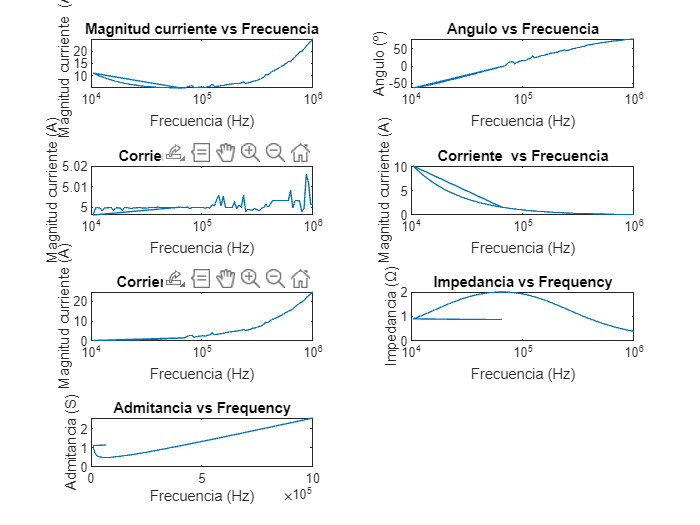

circuito_paralelo = tiledlayout(4,2)

nexttile
semilogx(f,paralelo_magnitud_corriente)
title('Magnitud curriente vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Magnitud curriente  (A)')

nexttile
semilogx(f,paralelo_angulo_corriente)
title('Angulo vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Angulo (º)')

nexttile
semilogx(f,paralelo_corriente_del_resistor)
title('Corriente vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Magnitud curriente (A)') 

nexttile
semilogx(f,paralelo_corrinte_del_inductor)
title('Corriente  vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Magnitud curriente (A)') 

nexttile
semilogx(f, paralelo_corriente_del_capacitor)
title('Corriente  vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Magnitud curriente (A)') 

nexttile
semilogx(f,Impedancia_paralelo)
title("Impedancia vs Frequency")
xlabel("Frecuencia (Hz)")
ylabel("Impedancia (Ω)")

nexttile
plot(f,admitancia_paralelo)
title("Admitancia vs Frequency")
xlabel("Frecuencia (Hz)")
ylabel("Admitancia (S)")